# **Lesson III.5:   Orthogonal Diagonalization**

**Symmetric matrices as a subset of Hermitian matrices.    **Recall that a real symmetric matrix is a square matrix $A\in{\mathbb R}^{n\times n}$ such that $A^T=A$.   Such matrices have the property that for all vectors ${\bf u}$ and ${\bf v}$ in ${\mathbb R}^n$

        (III.5.1a)        ${\bf u}^T A {\bf v}={\bf v}^TA{\bf u}\qquad\Rightarrow\qquad {\bf u}\cdot (A{\bf v})={\bf v}\cdot(A{\bf u})$.

While this might seem to be just a bit of curious algebra, it turns out that in a very wide range of applications this property plays a crucial role.   Since such matrices are of considerable significance in applications that necessarily make use of complex matrices, it is natural to consider how this property generalizes to complex vectors and matrices.    A Hermitian matrix is a square matrix $A\in{\mathbb C}^{n\times n}$ such that $A^H=A$ where $A^H$ denotes the conjugate transpose of $A$.   Such matrices have the property that for all vectors ${\bf u}$ and ${\bf v}$ in ${\mathbb C}^n$

        (III.5.1b)        ${\bf u}^H A {\bf v}={\bf v}^HA{\bf u}\qquad\Rightarrow\qquad {\bf u}\cdot (A{\bf v})={\bf v}\cdot(A{\bf u})$.

It is worth noting that the complex dot product (${\bf u}\cdot{\bf v}={\bf u}^H{\bf v}$) is not commutative:

        (III.5.2)         ${\bf u}\cdot{\bf v}=\big({\bf v}\cdot{\bf u}\big)^*$

where the asterisk (*) denotes complex conjugate.   

**Summary of results concerning diagonalization of Hermitian matrices**.  For a general $n\times n$ matrix, we know that

- there are $n$ eigenvalues (counted according to their multiplicities),

- each distinct eigenvalue has at least one eigenvector,

- a set of eigenvectors, each having a distinct eigenvalue, is independent.

There are, however, some potential complexities:

- eigenvalues may be complex even when the matrix is real,

- for eigenvalues with multiplicity greater than 1 the number of independent eigenvectors may be less than the multiplicity (implying the lack of an eigenbasis).

These complexities are fully resolved for the set of Hermitian matrices (which includes the real symmetric matrices).  Specifically, for a Hermitian matrix 

- there are $n$ real eigenvalues (counted according to their multiplicities),

- there are always $n$ linearly independent eigenvectors,

- there is an orthonormal eigenbasis.

This resolution guarantees that every Hermitian matrix (including every real symmetric matrix) can be diagonalized with an orthogonal eigenvector matrix.   This allows every $n\times n$ Hermitian matrix to be written as a linear combination of $n$ fewer rank-one orthogonal projection matrices.

**Examples illustrating results for Hermitian matrices**.   In the three examples below, notice that the eigenvalues are real, and eigenvectors are orthogonal.

A=[1 2; 2 4]

A =      1     2
     2     4


[S,D]=eig(sym(A))

$$S = \left(\begin{array}{cc} -2 & \frac{1}{2}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 0 & 0\\ 0 & 5 \end{array}\right)$$

S'*S    % diagonal Gram matrix implies orthogonal columns

$$ans = \left(\begin{array}{cc} 5 & 0\\ 0 & \frac{5}{4} \end{array}\right)$$

[U,~ ] = qr(S)      % using "Gram-Schmidt" to normalize vectors in S; ~ ignores R

$$U = \left(\begin{array}{cc} -\frac{2\,\sqrt{5}}{5} & \frac{\sqrt{5}}{5}\\ \frac{\sqrt{5}}{5} & \frac{2\,\sqrt{5}}{5} \end{array}\right)$$

U'*U    % check U is orthogonal

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

U*D*U'  % check orthogonal diagonalization

$$ans = \left(\begin{array}{cc} 1 & 2\\ 2 & 4 \end{array}\right)$$

A=[5 i; -i 5]

A =   5.000000000000000 + 0.000000000000000i  0.000000000000000 + 1.000000000000000i
  0.000000000000000 - 1.000000000000000i  5.000000000000000 + 0.000000000000000i


[S,D]=eig(sym(A))

$$S = \left(\begin{array}{cc} -\mathrm{i} & \mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 4 & 0\\ 0 & 6 \end{array}\right)$$

S'*S    % diagonal Gram matrix (using Hermitian transpose) implies orthogonal columns

$$ans = \left(\begin{array}{cc} 2 & 0\\ 0 & 2 \end{array}\right)$$

[U,~]=qr(S) %normalize columns of S

$$U = \left(\begin{array}{cc} -\frac{\sqrt{2}\,\mathrm{i}}{2} & \frac{\sqrt{2}\,\mathrm{i}}{2}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} \end{array}\right)$$

U'*U    % check U is orthogonal

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

U*D*U'  % check orthogonal diagonalization

$$ans = \left(\begin{array}{cc} 5 & \mathrm{i}\\ -\mathrm{i} & 5 \end{array}\right)$$

A=([2 i 0 0; -i 2 i 0; 0 -i 2 i; 0 0 -i 2]);
[S,D]=eig(A)     % numerical computation

S =   0.000000000000000 + 0.371748034460185i  0.000000000000000 - 0.601500955007546i  0.000000000000000 - 0.601500955007546i  0.000000000000000 - 0.371748034460185i
 -0.601500955007546 + 0.000000000000000i  0.371748034460185 + 0.000000000000000i -0.371748034460185 + 0.000000000000000i -0.601500955007545 + 0.000000000000000i
  0.000000000000000 - 0.601500955007546i  0.000000000000000 - 0.371748034460184i  0.000000000000000 - 0.371748034460184i  0.000000000000000 + 0.601500955007546i
  0.371748034460184 + 0.000000000000000i  0.601500955007546 + 0.000000000000000i -0.601500955007546 + 0.000000000000000i  0.371748034460185 + 0.000000000000000i


D =    0.381966011250105                   0                   0                   0
                   0   1.381966011250105                   0                   0
                   0                   0   2.618033988749895                   0
                   0                   0                   0   3.618033988749894


S'*S    % diagonal Gram matrix implies orthogonal columns

ans =    1.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
  -0.000000000000000   1.000000000000000  -0.000000000000000   0.000000000000000
   0.000000000000000  -0.000000000000000   1.000000000000000   0.000000000000000
  -0.000000000000000   0.000000000000000   0.000000000000000   1.000000000000000


[U,~]= qr(S)    % normalize columns of S (Gram-Schmidt)

U =   0.000000000000000 - 0.371748034460185i -0.000000000000000 + 0.601500955007546i  0.000000000000000 + 0.601500955007546i  0.000000000000000 + 0.371748034460185i
  0.601500955007546 + 0.000000000000000i -0.371748034460185 - 0.000000000000000i  0.371748034460185 - 0.000000000000000i  0.601500955007546 + 0.000000000000000i
  0.000000000000000 + 0.601500955007546i  0.000000000000000 + 0.371748034460185i  0.000000000000000 + 0.371748034460184i  0.000000000000000 - 0.601500955007546i
 -0.371748034460184 - 0.000000000000000i -0.601500955007546 - 0.000000000000000i  0.601500955007546 - 0.000000000000000i -0.371748034460185 + 0.000000000000000i


U'*U    % check U is orthogonal

ans =   1.000000000000000 + 0.000000000000000i -0.000000000000000 - 0.000000000000000i -0.000000000000000 - 0.000000000000000i  0.000000000000000 - 0.000000000000000i
 -0.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i -0.000000000000000 - 0.000000000000000i  0.000000000000000 - 0.000000000000000i
 -0.000000000000000 + 0.000000000000000i -0.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i  0.000000000000000 - 0.000000000000000i
  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i


U*D*U'  % check orthogonal diagonalization

ans =   2.000000000000000 + 0.000000000000000i  0.000000000000000 + 1.000000000000000i -0.000000000000001 + 0.000000000000001i -0.000000000000000 - 0.000000000000001i
  0.000000000000000 - 1.000000000000000i  1.999999999999999 + 0.000000000000000i  0.000000000000000 + 1.000000000000000i -0.000000000000000 - 0.000000000000000i
 -0.000000000000001 - 0.000000000000001i  0.000000000000000 - 1.000000000000000i  2.000000000000000 - 0.000000000000000i -0.000000000000000 + 1.000000000000000i
 -0.000000000000000 + 0.000000000000001i -0.000000000000000 + 0.000000000000000i -0.000000000000000 - 1.000000000000000i  2.000000000000000 + 0.000000000000000i


Here is an example that may seem to be a counterexample on first examination:

A=[1 2 2; 2 1 -2; 2 -2 1];
[S,D]=eig(sym(A))

$$S = \left(\begin{array}{ccc} -1 & 1 & 1\\ 1 & 1 & 0\\ 1 & 0 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} -3 & 0 & 0\\ 0 & 3 & 0\\ 0 & 0 & 3 \end{array}\right)$$

S'*S  

$$ans = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 2 & 1\\ 0 & 1 & 2 \end{array}\right)$$

The Gram matrix is not diagonal indicating that the eigenvectors are not orthogonal.   Close examination indicates that the two nonorthogonal eigenvectors are both associated with the eigenvalue $\lambda=3$.   That is, these eigenvectors are a basis for the two-dimensional null space of $A-3I$.  The issue is that MATLAB has simply failed to choose an orthogonal basis for this null space.   (It is nice to have someone, even a computer system, to blame for our problems.)   This issue can be resolved by applying Gram-Schmidt to these two vectors.    Since MATLAB was to blame, we will have MATLAB perform the equivalent of Gram-Schmidt (i.e., the QR factorization) on the whole matrix.   For computations by hand, you will likely want to avoid applying Gram-Schmidt to all the eigenvectors as only those belonging to a single eigenvalue are in need of orthogonalization.

[U,~]=qr(S);
simplify(U)

$$ans = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{3} & \frac{\sqrt{2}}{2} & \frac{\sqrt{6}}{6}\\ \frac{\sqrt{3}}{3} & \frac{\sqrt{2}}{2} & -\frac{\sqrt{6}}{6}\\ \frac{\sqrt{3}}{3} & 0 & \frac{\sqrt{6}}{3} \end{array}\right)$$

U*U'

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

U*D*U'

$$ans = \left(\begin{array}{ccc} 1 & 2 & 2\\ 2 & 1 & -2\\ 2 & -2 & 1 \end{array}\right)$$

**Why eigenvalues of Hermitian matrices must be real.**   Suppose $A^H=A$ and $A{\bf v}=\lambda{\bf v}$ where ${\bf v}\ne{\bf 0}$.   Multiplying the eigenvalue equation on the left by ${\bf v}^H$ implies

        (III.5.3a)        ${\bf v}^H A{\bf v}=\lambda{\bf v}^H{\bf v}$.

We note that taking the Hermitian transpose of the left-hand side shows that it is real:

        (III.5.3b)        $\big({\bf v}^HA{\bf v}\big)^H={\bf v}^HA^H{\bf v}={\bf v}^HA{\bf v}$.

Taking the Hermitian transpose of the right gives

        (III.5.3c)        $\big(\lambda{\bf v}^H{\bf v}\big)^H=\lambda^* {\bf v}^H{\bf v}$.

Hence $\lambda^*=\lambda$ implying that $\lambda$ is real.

**Why eigenvectors with different eigenvalues must be orthogonal.  **Suppose that $A^H=A$, $A{\bf v}=\lambda{\bf v}$, $A{\bf u}=\mu{\bf u}, {\bf v}\ne{\bf 0}, {\bf u}\ne{\bf 0}, \lambda\ne\mu$.   That is, we have two eigenvectors with different eigenvalues.

        (III.5.4a)        $\lambda {\bf u}^H{\bf v}={\bf u}^HA{\bf v}={\bf u}^HA^H{\bf v}=\big({\bf v}^HA{\bf u}\big)^H=\big(\mu{\bf v}^H{\bf u}\big)^H=\mu{\bf u}^H{\bf v}\qquad\Rightarrow$

        (III.5.4b)        $(\lambda-\mu){\bf u}^H{\bf v}=0\qquad\Rightarrow\qquad {\bf u}^H{\bf v}=0$.

**Orthogonal diagonalization.    **If $A$ is real symmetric then $A$ can be diagonalized with an orthonormal eigenbasis.  Thus,

        (III.5.5)        $A=UDU^T$ 

where $U$is orthogonal and $D$ is diagonal with real diagonal elements.    The process of computing an orthogonalization requires but one extra step beyond that of ordinary diagonalization:   the orthonormalization of the eigenbasis.    For a real symmetric matrix $A$, a diagonalization $A=SDS^{-1}$ can be modified by applying the Gram-Schmidt process to the columns of $S$ to obtain $U$; the diagonal matrix $D$ is the same for both factorizations.  

A=[1 2 1 -1; 2 4 2 -2; 1 2 1 -1; -1 -2 -1 1]

A =      1     2     1    -1
     2     4     2    -2
     1     2     1    -1
    -1    -2    -1     1


[S,D]=eig(sym(A))

$$S = \left(\begin{array}{cccc} -2 & -1 & 1 & -1\\ 1 & 0 & 0 & -2\\ 0 & 1 & 0 & -1\\ 0 & 0 & 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 7 \end{array}\right)$$

S'*S   % Checking the Gram matrix of the eigenvector matrix

$$ans = \left(\begin{array}{cccc} 5 & 2 & -2 & 0\\ 2 & 2 & -1 & 0\\ -2 & -1 & 2 & 0\\ 0 & 0 & 0 & 7 \end{array}\right)$$

The first three eigenvectors, the basis for $\text{nul}(A)$, are not orthogonal.   Applying the QR factorization (algebraically equivalent to Gram-Schmidt) rectifies this issue:

[U,~]=qr(S);
U=simplify(U)

$$U = \left(\begin{array}{cccc} -\frac{2\,\sqrt{5}}{5} & -\frac{\sqrt{30}}{30} & \frac{\sqrt{42}}{42} & -\frac{\sqrt{7}}{7}\\ \frac{\sqrt{5}}{5} & -\frac{\sqrt{30}}{15} & \frac{\sqrt{42}}{21} & -\frac{2\,\sqrt{7}}{7}\\ 0 & \frac{\sqrt{30}}{6} & \frac{\sqrt{42}}{42} & -\frac{\sqrt{7}}{7}\\ 0 & 0 & \frac{\sqrt{42}}{7} & \frac{\sqrt{7}}{7} \end{array}\right)$$

U'*U    % verifying orthonormality of the eigenbasis

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

U*D*U'    % verifying the orthogonal diagonalization

$$ans = \left(\begin{array}{cccc} 1 & 2 & 1 & -1\\ 2 & 4 & 2 & -2\\ 1 & 2 & 1 & -1\\ -1 & -2 & -1 & 1 \end{array}\right)$$

**Important short cuts to orthonormalization.   **While applying Gram-Schmidt to the eigenvector matrix is a conceptually simple solution, the full implementation of Gram-Schmidt for the entire eigenvector matrix is often both onerous and unnecessary.   Because eigenvectors belonging to different eigenvalues necessarily are orthogonal, the full process of orthogonalizing eigenvectors need only be implemented within the groups of eigenvectors sharing a common eigenvalue.   In the example above, only the first three eigenvectors having $\lambda =0$ needed this attention.   For symmetric matrices where all the eigenvalues have a multiplicity of 1, every eigenbasis will be orthogonal.    Whether orthogonal from the beginning or due to application of Gram-Schmidt to the groups of eigenvectors with common eigenvalues, it is necessary to assure that the basis is normalized (each vector dividend by its length) in order to assure we have the orthonormal eigenbasis needed for orthogonal diagonalization.

**A modest example.**   Because meaningful examples require multiple eigenvalues and an eigenvalue with multiplicity of at least two, the smallest example illustrating the process is $3\times 3$ which is already challenging when computing by hand.   Nonetheless, exploring such an example in detail is very helpful for fully understanding the process:   Find the orthogonal diagonalization of

        
$$A=\left[\matrix{5&4&2\cr4&5&2\cr2&2&2}\right].
$$
                    
$$\matrix{\bullet\cr 1 \cr 1}~
\left|\matrix{5&4&2\cr4&5&2\cr2&2&2}\right|=

\left|\matrix{5&4&2\cr-1&1&0\cr-3&-2&0}\right|=2\left|\matrix{-1&1\cr-3&-2}\right|=2(2+3)=10

$$


        
$$p_A(\lambda)=-\lambda^3+(5+5+2)\lambda^2-\left(\left|\matrix{5&4 \cr 4&5 }\right|+\left|\matrix{5&2\cr2&2}\right|+\left|\matrix{5&2\cr2&2}\right|\right)\lambda+10$$


                    
$$=-\lambda^3+12\lambda^2-(9+6+6)\lambda+10=-\lambda^3+12\lambda^2-21\lambda+10$$


With candidate rational roots $\pm1, \pm2,\pm5,\pm10$, we happily discover our first guess (hopefully) $\lambda=1$is indeed a root--in fact, a double root.  Hence,

$\lambda_1=\lambda_2=1$ and $\lambda_3=10$.   Eigenvalues in hand, we search for eigenvectors:


$$\underline{\lambda_1=\lambda_2=1}:\qquad A-\lambda_1 I=\left[\matrix{4&4&2\cr4&4&2\cr2&2&1}\right]\sim\left[\matrix{2&2&1\cr0&0&0\cr0&0&0}\right]\sim\left[\matrix{1&1&1/2\cr0&0&0\cr0&0&0}\right]
\quad\Rightarrow\quad{\bf v}_1=\left[\matrix{-1\cr 1\cr 0}\right]\quad\text{and}\quad {\bf v}_2=\left[\matrix{-1/2\cr0\cr1}\right]$$


We see that ${\bf v}_1\cdot{\bf v}_2\ne0$.   Since our goal is orthogonal diagonalization, we fix the orthogonality problem by redefining ${\bf v}_2$ using Gram-Schmidt:

        ${\bf v}_2= \left[\matrix{-1/2\cr0\cr1}\right]~-~\frac{1/2}{1+1}\left[\matrix{-1\cr1\cr0}\right]~=~\left[\matrix{-1/2\cr0\cr1}\right]~-~\frac{1}{4}\left[\matrix{-1\cr1\cr0}\right]=\left[\matrix{-1/4\cr-1/4\cr 1}\right]$.


$$\underline{\lambda_3=10}:\qquad A-\lambda_3 I=\left[\matrix{-5 &4 & 2 \cr 4&-5&2\cr 2 & 2 & -8}\right]\sim
\left[\matrix{2&2&-8\cr 4 & -5&2\cr 0 &0 &0}\right]\sim\left[\matrix{2&2&-8\cr 0&-9&18\cr 0&0&0}\right]\sim
\left[\matrix{1&1&-4\cr0&1&-2\cr0&0&0}\right]\sim\left[\matrix{1&0&-2\cr0&1&-2\cr0&0&0}\right]\quad\Rightarrow\quad{\bf v}_3=\left[\matrix{2\cr2\cr1}\right]
$$


Normalizing the orthogonal eigenbasis gives

        $A=UDU^T\quad\text{where}\quad U=
\left[\matrix{
\frac{-\sqrt{2}}{2} &-\frac{\sqrt{2}}{6}&~\frac23 \cr \frac{\sqrt{2}}{2}&-\frac{\sqrt{2}}{6}&~ \frac23\cr 0 & \frac{2\sqrt{2}}{3} & ~\frac13}\right]\quad\text{and}\quad D=
\left[\matrix{1&0&0\cr 0&1&0 \cr 0&0&10}\right]$.

**Symmetric matrix as a linear combination of orthogonal projections.   **Applying outer product expansion to the orthogonal diagonalization of $A$ gives a linear combination of rank one orthogonal projections.

        (III.5.6)        $A=UDU^T=\left[\matrix{{\bf u}_1 & \cdots & {\bf u}_n}\right]\left[\matrix{\lambda_1 & & & \cr & \lambda_2 & &\cr
 & & \ddots & \cr
& & & \lambda_n}\right] \left[\matrix{{\bf u}_1 & \cdots & {\bf u}_n}\right]^T=\left[\lambda_1\matrix{{\bf u}_1 & \cdots & \lambda_n{\bf u}_n}\right]\left[\matrix{{\bf u}_1 & \cdots & {\bf u}_n}\right]^T$

                        $\qquad= \lambda_1{\bf u}_1{\bf u}_1^T~+~\lambda_2{\bf u}_2{\bf u}_2^T~+~\cdots~+~\lambda_n{\bf u}_n{\bf u}_n^T
$.

Recall that the action of $P_\ell={\bf u}_\ell{\bf u}_\ell^T$ is orthogonal projection onto the one-dimensional subspace $\text{Span}\{{\bf u}_\ell\}$:

        $P_\ell^2=\big({\bf u}_\ell {\bf u}_\ell^T\big)\big({\bf u}_\ell {\bf u}_\ell^T\big)={\bf u}_\ell \big({\bf u}_\ell^T{\bf u}_\ell\big) {\bf u}_\ell^T={\bf u}_\ell {\bf u}_\ell^T=P_\ell$,

        $P_\ell^T=\big({\bf u}_\ell {\bf u}_\ell^T\big)^T={\bf u}_\ell {\bf u}_\ell^T=P_\ell$.

**Geometric interpretation.   **A linear map $T:{\mathbb R}^n\to{\mathbb R}^n$ defined by $T({\bf x})=A{\bf x}$ where $A^T=A$ stretches vectors in the $n$ orthogonal directions defined by the eigenvectors by factors given by the eigenvalues.    The result is that the image of the unit $n$-sphere is an ellipsoid where the principal axes are in the direction of the eigenvectors and the lengths of these axes is given by the magnitudes of the eigenvalues.

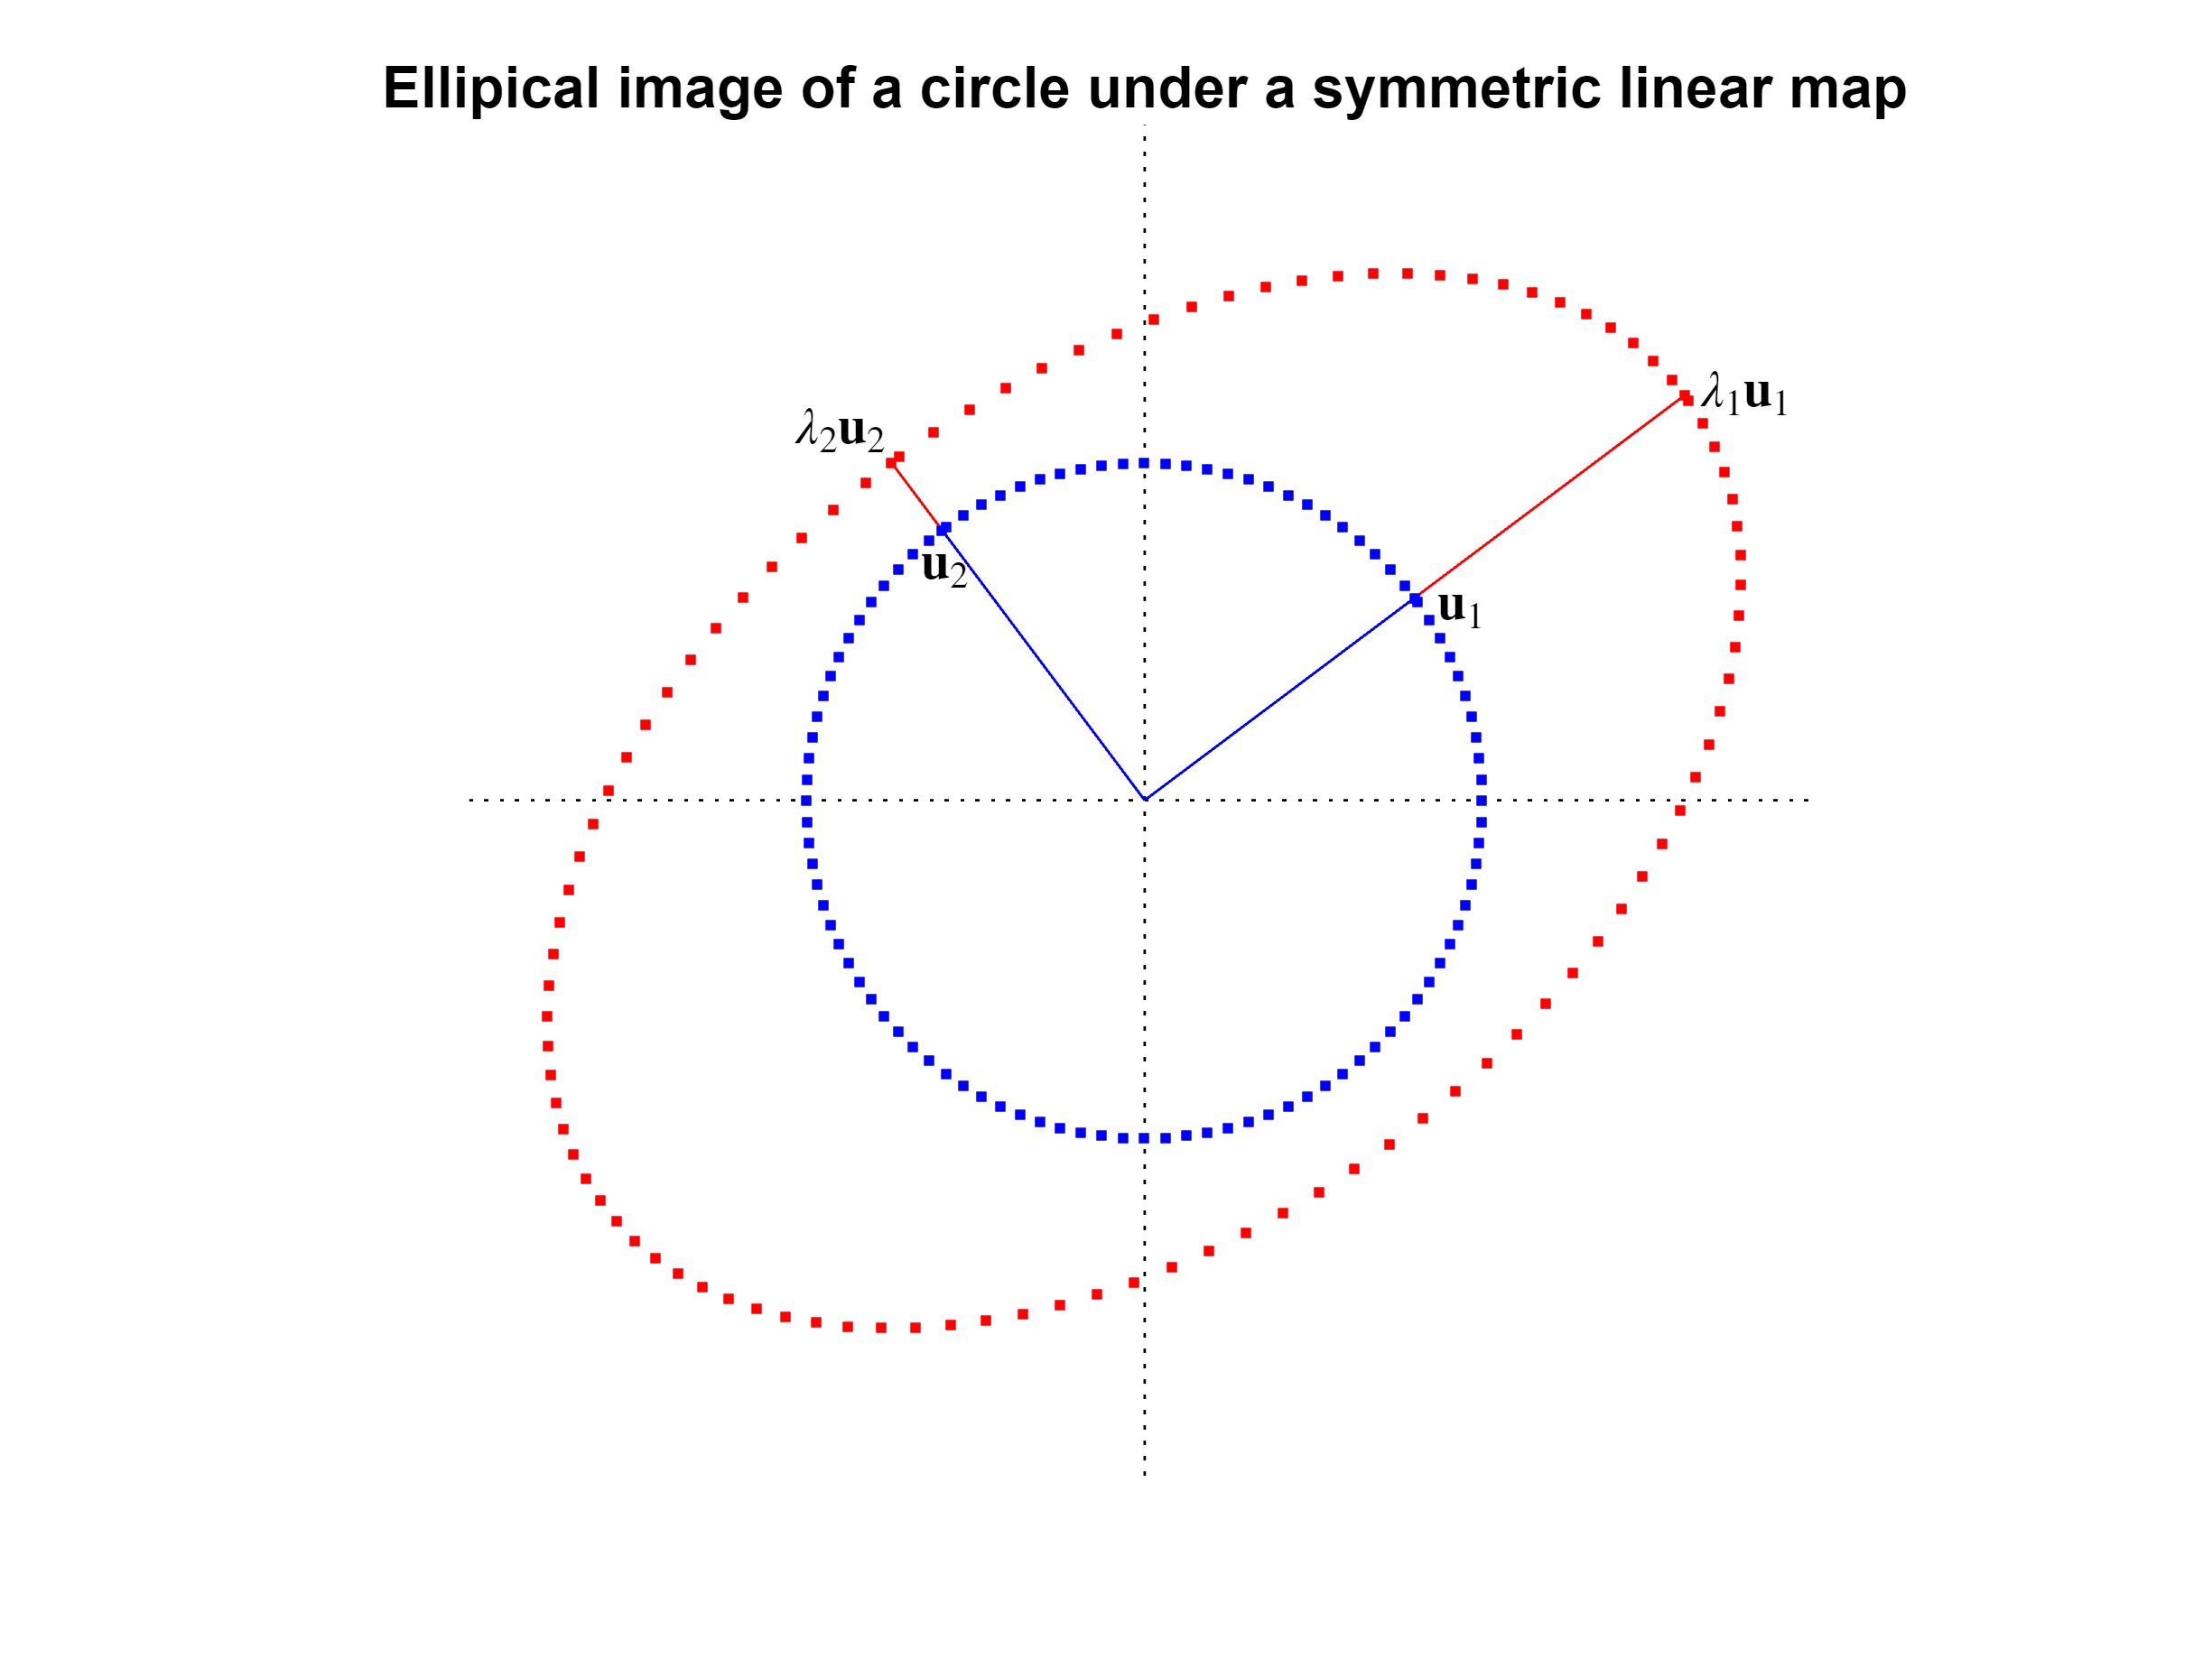

figIII5a()

**Follow-up Problems**

**Problem III.5.1:   **Compute the following "dot" products:


$$\qquad\text{(a)}\quad\left[\matrix{1\cr0\cr1}\right]\cdot\left[\matrix{1\cr2\cr-1}\right]
\qquad\text{(b)}\quad\left[\matrix{1\cr1\cr1\cr1}\right]\cdot\left[\matrix{1\cr-1\cr-1\cr1}\right]
\qquad\text{(c)}\quad\left[\matrix{1\cr i\cr1+i\cr2+3i}\right]\cdot\left[\matrix{1\cr i \cr1-i\cr 3-i}\right]
\qquad\text{(d)}\quad\left[\matrix{1\cr i \cr1-i\cr 3-i}\right]\cdot\left[\matrix{1\cr i\cr1+i\cr2+3i}\right]$$


**Problem  III.5.2:**   Compute each of the following expressions:


$$\qquad\text{(a)}\quad \left[\matrix{1\cr0\cr1}\right]\cdot\left[\matrix{2&1&0\cr1&2&1\cr0&1&2}\right]\left[\matrix{1\cr2\cr-1}\right]
\qquad\text{(b)}\quad\left[\matrix{1\cr2\cr-1}\right]\cdot\left[\matrix{2&1&0\cr1&2&1\cr0&1&2}\right] \left[\matrix{1\cr0\cr1}\right]
\qquad\text{(c)}\quad \left[\matrix{1\cr0\cr1}\right]\cdot\left[\matrix{2&1&0\cr-1&2&1\cr0&1&2}\right]\left[\matrix{1\cr2\cr-1}\right]
\qquad\text{(d)}\quad\left[\matrix{1\cr2\cr-1}\right]\cdot\left[\matrix{2&1&0\cr-1&2&1\cr0&-1&2}\right] \left[\matrix{1\cr0\cr-1}\right]$$


**Problem  III.5.3:**   Compute each of the following expressions:


$$\qquad\text{(a)}\quad \left[\matrix{1\cr i\cr1}\right]\cdot\left[\matrix{2&i&0\cr i&2&i\cr0&i&2}\right]\left[\matrix{1+i\cr2+i\cr-1+i}\right]
\qquad\text{(b)}\quad\left[\matrix{1\cr2\cr-1}\right]\cdot\left[\matrix{2&i&0\cr i&2&i\cr0&i&2}\right] \left[\matrix{1\cr i\cr1}\right]
\qquad\text{(c)}\quad \left[\matrix{1\cr i\cr1}\right]\cdot\left[\matrix{2&i&0\cr-i&2&i\cr0&i&2}\right]\left[\matrix{1\cr2\cr-1}\right]
\qquad\text{(d)}\quad\left[\matrix{1\cr2\cr-1}\right]\cdot\left[\matrix{2&i&0\cr-i&2&i\cr0&i&2}\right] \left[\matrix{1\cr i\cr-1}\right]$$


**Problem III.5.4:  **Find the orthogonal diagonalization of the following matrices.


$$\qquad\text{(a)}\quad \left[\matrix{1&1\cr1&1}\right]\qquad \text{(b)} \quad\left[\matrix{1 & 1 \cr 1 & 2}\right]\qquad\text{(c)}\quad\left[\matrix{1 & 0\cr0&1}\right] \qquad\text{(d)}\quad\left[\matrix{\pi&1\cr1&\sqrt{2}}\right]\qquad\text{(e)}\quad \left[\matrix{1 & 1+i\cr 1-i & 1}\right]$$


**Problem III.5.5:  **Find the orthogonal diagonalization of the following matrices.


$$\qquad\text{(a)}\quad\left[\matrix{1&2&2\cr 2&4&4\cr 2&4&4}\right]\qquad
\qquad\text{(b)}\quad\left[\matrix{-2&2&2\cr 2&1&4\cr 2&4&1}\right]\qquad
\qquad\text{(c)}\quad\left[\matrix{0&i&0\cr-i&0&i\cr0 & -i& 0}\right]$$


**Problem III.5.6:**  Suppose that ${\bf u}$ and ${\bf v}$ are unit vectors in ${\mathbb R}^n$.   Determine when the $n\times n$ rank 1 matrix $A={\bf u}{\bf v}^T$ can be orthogonally diagonalized.

**Problem III.5.7:**  Suppose that ${\bf u}$ and ${\bf v}$ are unit vectors in ${\mathbb R}^n$.   Determine when the $n\times n$ rank 1 matrix $A={\bf u}{\bf v}^T$ can be diagonalized.

**Problem III.5.8:**  Suppose that ${\bf u}$ and ${\bf v}$ are unit vectors in ${\mathbb R}^n$.   Determine when the $n\times n$ rank 1 matrix $A={\bf u}{\bf v}^T$ cannot be diagonalized.

**Problem III.5.9:  **Determine the largest value of $\left[\matrix{ x& y}\right]\left[ \matrix{ 4 & 1 \cr 1 & 4}\right]\left[\matrix{x\cr y}\right]$if $x^2+y^2=1$.

**Problem III.5.10:  **Determine the smallest value of $\left[\matrix{ x& y}\right]\left[ \matrix{ 4 & 1 \cr 1 & 4}\right]\left[\matrix{x\cr y}\right]$if $x^2+y^2=1$.

function figIII5a()
    hold on
    title("Ellipical image of a circle under a symmetric linear map")
    axis([-2 2 -2 2])
    axis square
    axis off
    plot([-2 2],[0 0],':k')
    plot([0 0],[-2 2],':k')
        plot([0 8/5],[0 6/5],'r');
    plot(8/5,6/5,'r.')
    text(8/5+0.03,6/5+0.01,'$\lambda_1{\bf u}_1$','Interpreter','latex')
    plot([0 4/5],[0 3/5],'b');
    plot(4/5,3/5,'b.')
    text(4/5+0.05,3/5-0.02,'${\bf u}_1$','Interpreter','latex')
    plot([0 -3/4],[0 4/4],'r');
    plot(-3/4,4/4,'r.')
    text(-3/4-0.3,4/4+0.1,'$\lambda_2{\bf u}_2$','Interpreter','latex')
    plot([0 -3/5],[0 4/5],'b');
    plot(-3/5,4/5,'b.')
    text(-3/5-0.08,4/5-0.1,'${\bf u}_2$','Interpreter','latex')
    theta=0.0:pi/50:2*pi;
    circle=[cos(theta); sin(theta)];
    plot(circle(1,:),circle(2,:),'.b')
    icircle=[173/100 9/25; 9/25 38/25]*circle;
    plot(icircle(1,:),icircle(2,:),'.r')
end